% Define the data for lower limit, upper limit, and frequency
lowerLimits = [300,310,320,330,340,350,360,370]; 
upperLimits = [310,320,330,340,350,360,370,380]; 
frequencies = [6,17,27,48,38,24,20,9];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

       300           310            6    
       310           320           17    
       320           330           27    
       330           340           48    
       340           350           38    
       350           360           24    
       360           370           20    
       370           380            9    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 340.45


fprintf('Median: %.2f\n', medianValue);

Median: 335.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 335.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 17.12


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 324.10


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 10.90


fprintf('Karl: %.2f\n', Karl);

Karl: 0.32


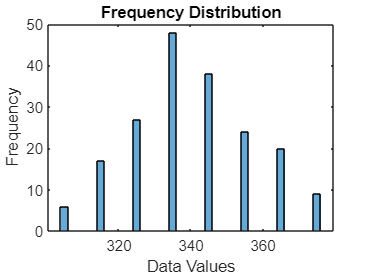


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');